Load Station Aloha Temperature data

T: temp (°C), t: time, z: depth (m)

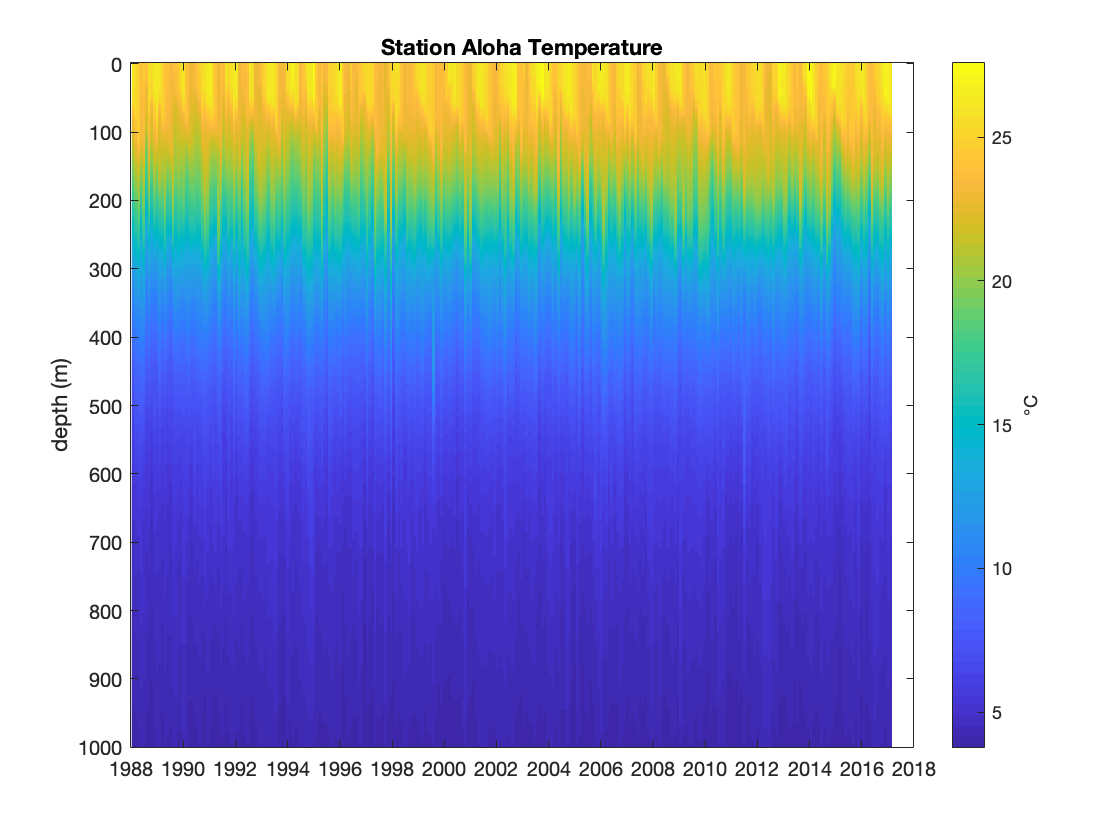

load HOTS_Temp.mat
nt = length(t);
nz = length(z);

figure (1)
imagesc(t,z,T)
ylabel('depth (m)')
datetick
cb = colorbar;
ylabel(cb,'°C')
title('Station Aloha Temperature')

Remove time average

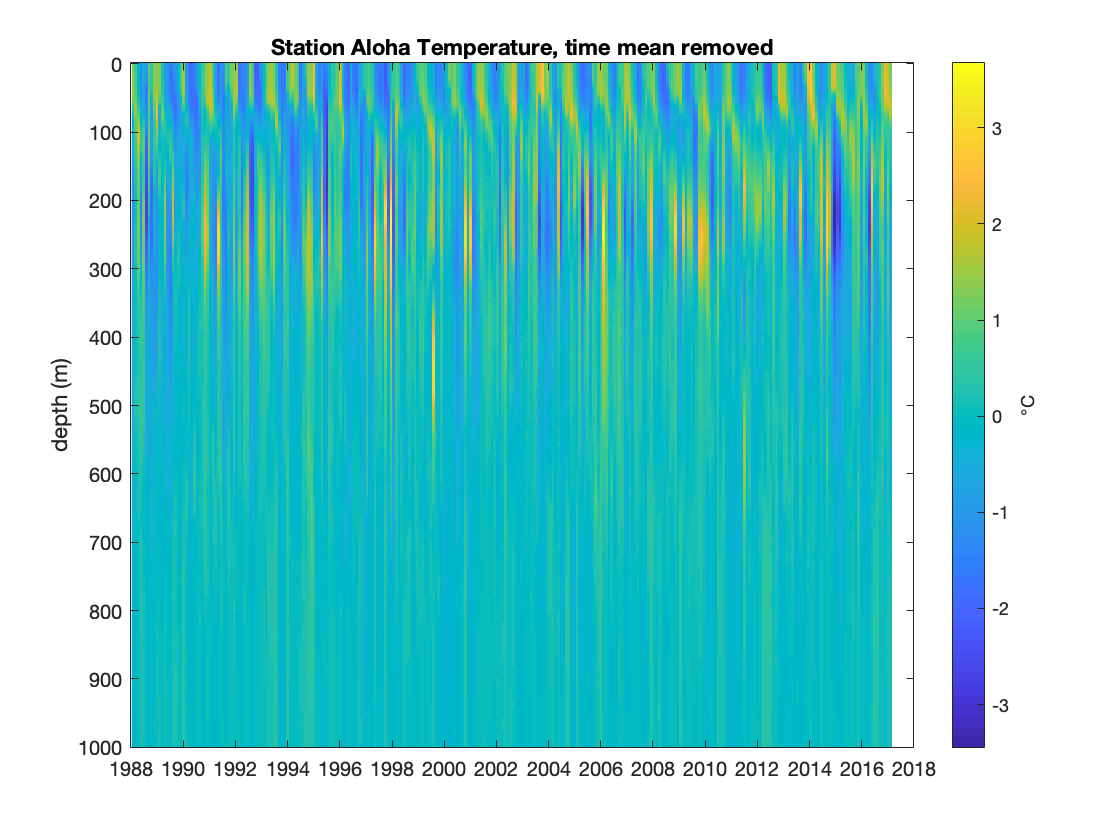

Td = detrend(T',0)'; % takes out mean of columns of T
figure (2)
imagesc(t,z,Td)
ylabel('depth (m)')
datetick
cb = colorbar;
ylabel(cb,'°C')
title('Station Aloha Temperature, time mean removed')

Covariance matrix, time average

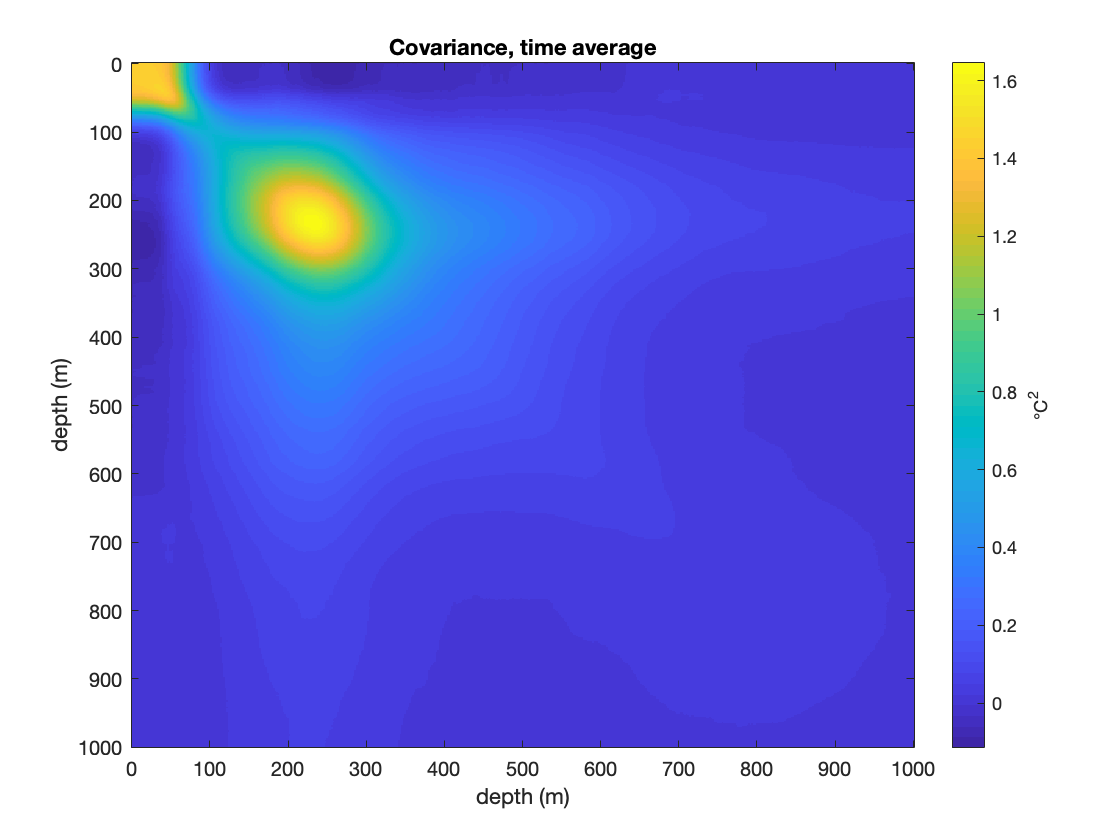

C = 1/(nt-1)*(Td*Td');

figure (3)
imagesc(z,z,C)
cb = colorbar;
ylabel(cb,'°C^2')
ylabel('depth (m)')
xlabel('depth (m)')
title('Covariance, time average')

Compute EOF

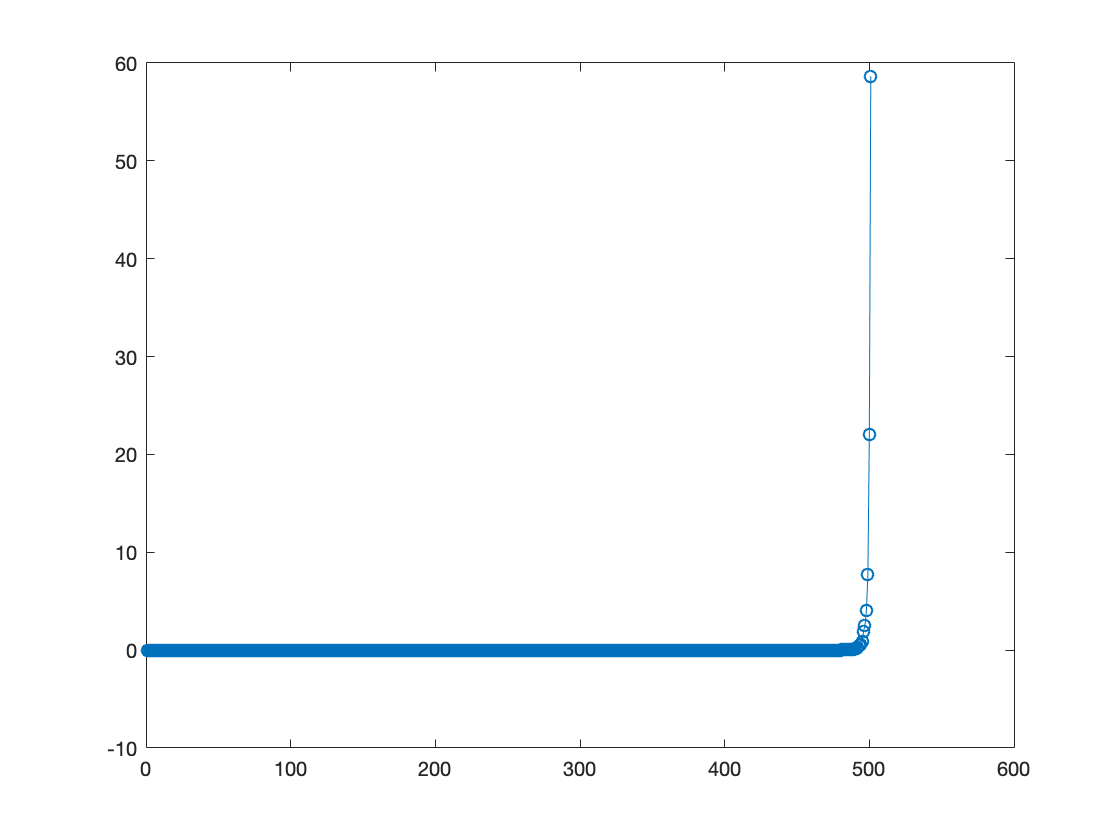

[e,lambda] = eig(C);
lambda = diag(lambda);
pvar = lambda/sum(lambda)*100;

figure (4)
plot(pvar,'o-')

Reverse the order of the modes

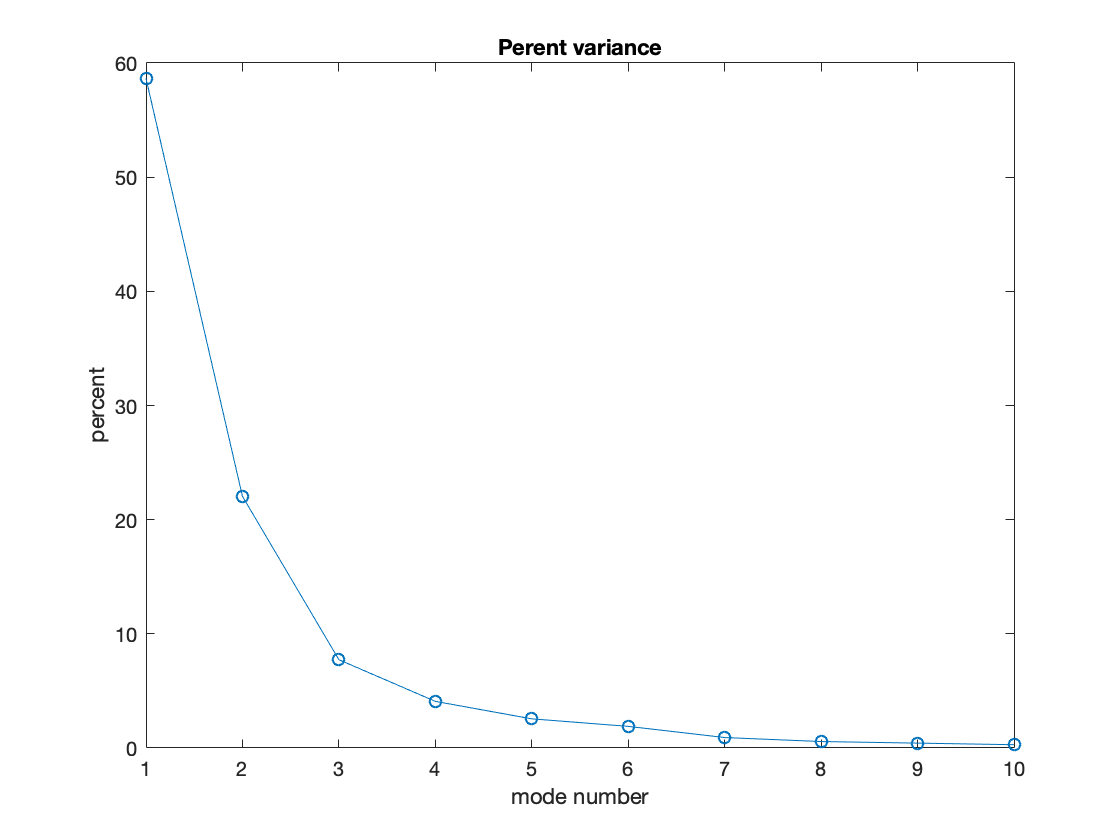

e = fliplr(e);
lambda = flipud(lambda);
pvar = flipud(pvar);

figure (5)
plot(pvar,'o-')
xlim([1 10])
title('Perent variance')
xlabel('mode number')
ylabel('percent')

Plot the cumulative variance explained

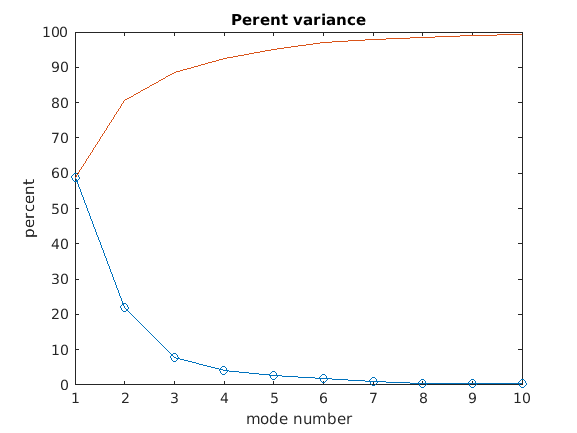

hold on
plot(cumsum(pvar))

Plot eigenvectors  (EOFs)

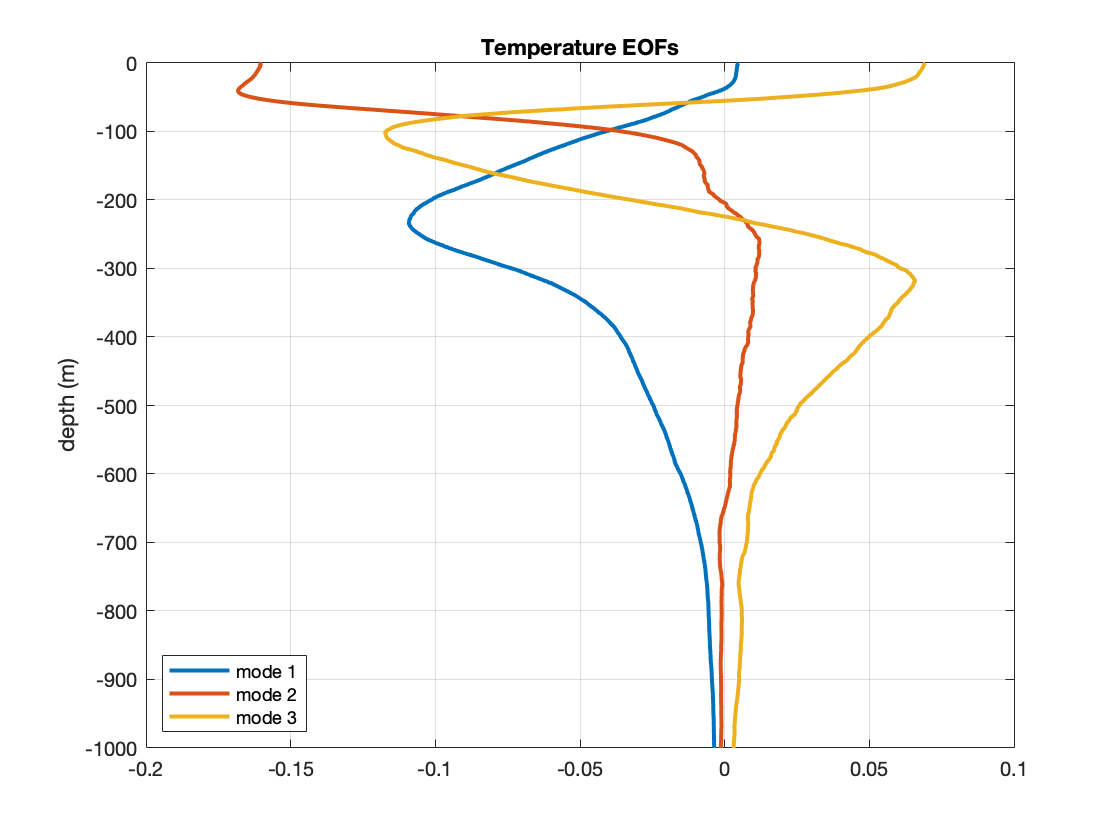

figure (6)
plot(e(:,1:3),-z,'LineWidth',2) % plot eigenvectors  against depth
% last mode, gives us connections in variability between the first two
% modes, first two mdoes explain similar pattern in mixed layer and
% thermocline?
ylabel('depth (m)')
title('Temperature EOFs')
grid on
legend('mode 1','mode 2','mode 3')
legend('location','SouthWest')

Plot temporal expansions (PCs) Principal components

mode1 baroclinic mode? - sea level inc corresponds to thermocline decrease, convergence, anti-correlation,

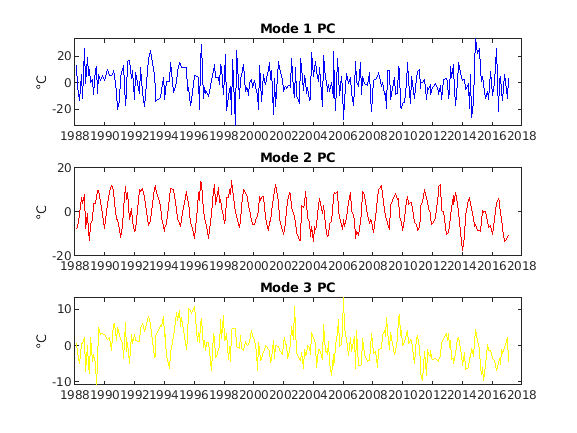

% MODES IN TIME
A = Td'*e;
figure (7)
subplot(311)
plot(t,A(:,1))
ylabel('°C')
title('Mode 1 PC')
datetick
subplot(312)
plot(t,A(:,2))
ylabel('°C')
title('Mode 2 PC')
datetick
subplot(313)
plot(t,A(:,3))
ylabel('°C')
title('Mode 3 PC')
datetick